# Example 6.21: 2D Fourier Transform of Filters

Note: this script reproduces the filters of Example 6.21 (Section 6.3.5) of **Statistics for Chemical Engineers**: 2D uniform and Gaussian filters and their Fourier transforms. Victor Z UW-Madison, 2020 illustrate fourier transform of different 2D filters

clc;  clear all; close all hidden; format short;

% size of signals
L=50;
c=linspace(0.99,0.0,64)';
C=[c,c,c];

## Uniform filter

create 2D rectangular pulse

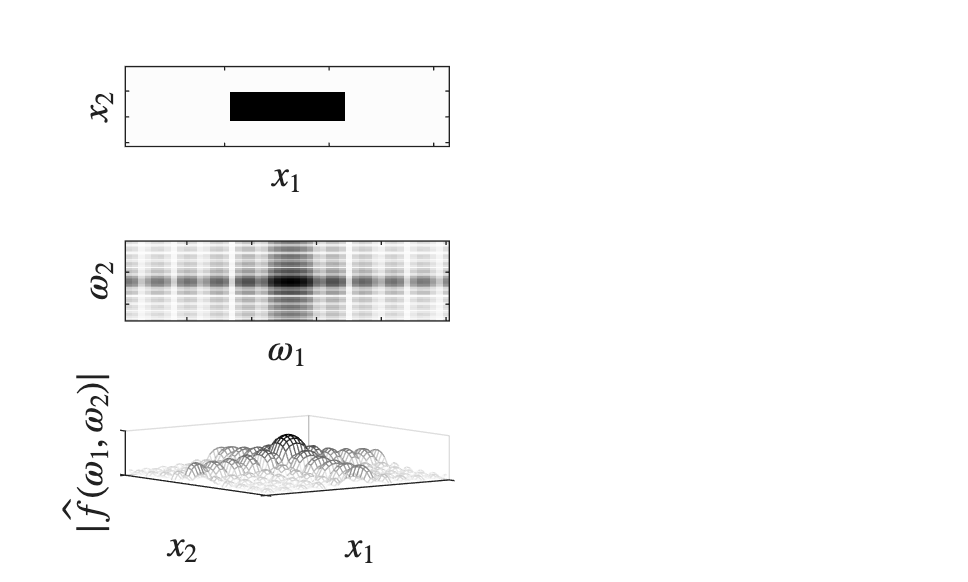

f=zeros(L,L);
f(20:30,20:30)=1;

subplot(3,2,1)
imagesc(f(10:40,10:40))
colormap(C);
set(gca,'YTickLabel',[]);
set(gca,'XTickLabel',[]);
set(gca,'ZTickLabel',[]);
ylabel('$x_2$','Interpreter','Latex','FontSize',14)
xlabel('$x_1$','Interpreter','Latex','FontSize',14)

% get fourier transform
m=log(1+abs(fft2(f))); % rescale to maximize visibility
mf=fftshift(m);
subplot(3,2,3)
imagesc(mf)
colormap(C);
set(gca,'YTickLabel',[]);
set(gca,'XTickLabel',[]);
set(gca,'ZTickLabel',[]);
ylabel('$\omega_2$','Interpreter','Latex','FontSize',14)
xlabel('$\omega_1$','Interpreter','Latex','FontSize',14)

subplot(3,2,5)
mesh(mf)
set(gca,'YTickLabel',[]);
set(gca,'XTickLabel',[]);
set(gca,'ZTickLabel',[]);
ylabel('$x_2$','Interpreter','Latex','FontSize',14)
xlabel('$x_1$','Interpreter','Latex','FontSize',14)
zlabel('$|\hat{f}(\omega_1,\omega_2)|$','Interpreter','Latex','FontSize',14)

## Gaussian filter

create 2D Gaussian filter

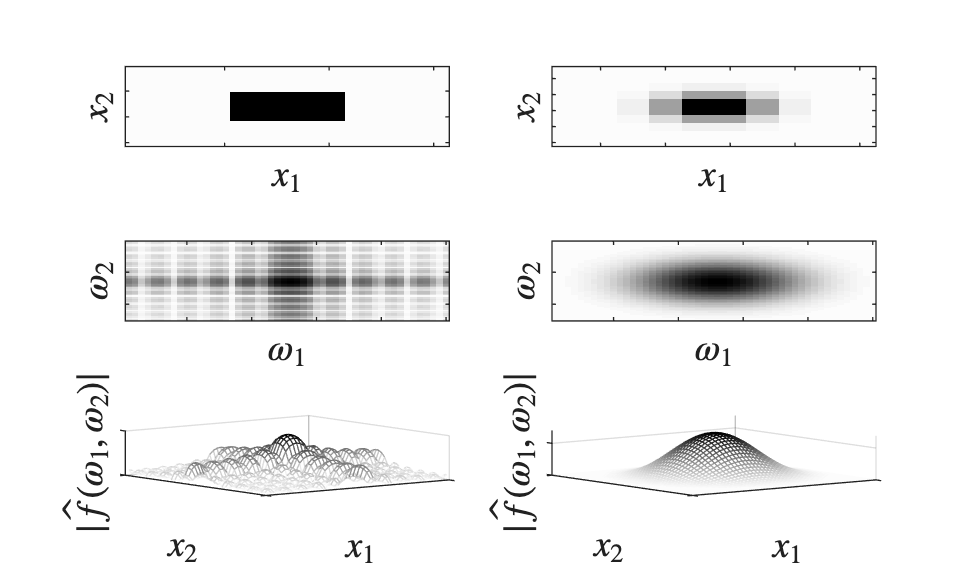

sigma=1;
f = fspecial('gaussian',L,sigma);

subplot(3,2,2)
imagesc(f(21:30,21:30))
colormap(C);
set(gca,'YTickLabel',[]);
set(gca,'XTickLabel',[]);
set(gca,'ZTickLabel',[]);
ylabel('$x_2$','Interpreter','Latex','FontSize',14)
xlabel('$x_1$','Interpreter','Latex','FontSize',14)

% get fourier transform
m=log(1+abs(fft2(f))); % rescale to maximize visibility
mf=fftshift(m);
subplot(3,2,4)
imagesc(mf)
colormap(C);
set(gca,'YTickLabel',[]);
set(gca,'XTickLabel',[]);
set(gca,'ZTickLabel',[]);
ylabel('$\omega_2$','Interpreter','Latex','FontSize',14)
xlabel('$\omega_1$','Interpreter','Latex','FontSize',14)

subplot(3,2,6)
mesh(mf)
set(gca,'YTickLabel',[]);
set(gca,'XTickLabel',[]);
set(gca,'ZTickLabel',[]);
ylabel('$x_2$','Interpreter','Latex','FontSize',14)
xlabel('$x_1$','Interpreter','Latex','FontSize',14)
zlabel('$|\hat{f}(\omega_1,\omega_2)|$','Interpreter','Latex','FontSize',14)

print -depsc -r1200 ch6_2dfourierfilter.eps

## Note

As in the book, the Gaussian filter keeps only the low frequencies (the bright region in the middle of its spectrum), which is why it preserves only coarse features.